# `inset_unproj` documentation

`inset_unproj` is part of Antarctic Mapping Tools for Matlab (Greene et al., 2017). See `List_of_Functions.mlx` for a complete list of functions in AMT.

The `inset_unproj` function places a polar stereographic inset map on an unprojected map of part of Antarctica. This function will most likely be useful for oceanographers who use data that are equally spaced in geographic grid coordinates and who want an unprojected map with south on the bottom. 

## Syntax

## Description

inset_unproj(InsetLocation) places an inset map in the location InsetLocation, which can be 'southeast' or 'se' lower right corner 'northwest' or 'nw' upper left corner 'northeast' or 'ne' upper right corner 'southwest' or 'sw' lower left corner

inset_unproj(...,'insetsize',sizefraction) specifies size of the inset as a fraction of the width of the current map. Default sizefraction is 0.25. 

inset_unproj(...,'frame','off') removes frame from the inset. 

h = inset_unproj(...) returns a handle h of inset map axes. 

## Example

Here's a map of Getz Ice Shelf and the Amundsen Sea Embayment. For context I'm using [Antarctic Boundaries](http://www.mathworks.com/matlabcentral/fileexchange/60246) from Mouginot et al. After you've plotted all your data, call `inset_unproj` and specify which corner you'd like to put the inset in. Below I'm also specifying that the inset should be much larger than the default quarter-height size, and should instead be half the map height. Also setting `'frame','off'` removes the box from around the inset map. 

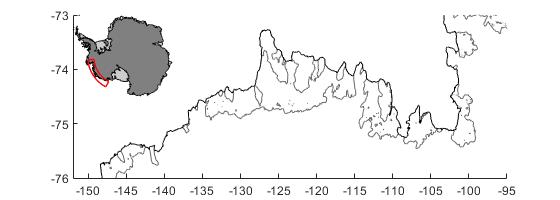

% Get gronding line and coast line data: 
[gllat,gllon] = antbounds_data('gl'); 
[coastlat,coastlon] = antbounds_data('coast'); 

% Initialize a figure: 
figure('pos',[100 100 560 200])

% Set axis limits to longitude and latitude range of interest: 
axis([-152 -95 -76 -73])
hold on

% Plot grounding line and coast line: 
plot(gllon,gllat,'-','color',0.4*[1 1 1]) 
plot(coastlon,coastlat,'k') 

% Make an inset map: 
inset_unproj('nw','insetsize',0.5,'frame','off')

## Zooming within the inset map itself

If you'd like to zoom the inset map itself, return a handle of the inset map, make the inset map the current axes, and then zoom manually by setting axis limits. Here's how: 

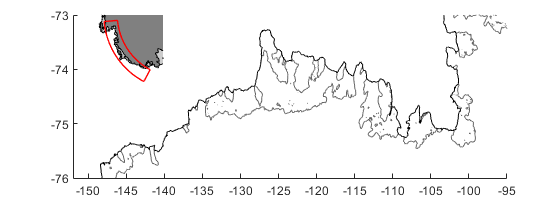

% Make an inset and return a handle h: 
h = inset_unproj('nw','insetsize',0.5,'frame','off'); 

% Make the inset axes current: 
axes(h) 

% Zoom the inset map to polar stereographic coordinates of your choosing: 
axis([-2400 -400 -2000 0]*1000)

## Citing AMT

If this function or any other part of Antarctic Mapping Tools is useful for you, please cite the paper that describes AMT. 

Greene, C. A., Gwyther, D. E., & Blankenship, D. D. Antarctic Mapping Tools for Matlab.  *Computers & Geosciences*. 104 (2017) pp.151-157. [doi:10.1016/j.cageo.2016.08.003](http://dx.doi.org/10.1016/j.cageo.2016.08.003).

## Author Info

This function was written by [Chad Greene](http://www.chadagreene.com) of the University of Texas Institute for Geophysics (UTIG), May 2017, for inclusion in the Antarctic Mapping Tools package. 